# Lymphography

Performs outlier detection on the Lymphography dataset from the University Medical Centre, Institute of Oncology, Ljubljana, Yugoslavia.

## Setup

clc;
clear all;
close all;
rng(1634256, "twister");

addpath(genpath(fileparts(which(mfilename))));

## Load Data

opts = delimitedTextImportOptions("NumVariables", 19);

% Specify range and delimiter
opts.DataLines = [1, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["class", "lymphatics", "block_of_affere", "bl_of_lymph_c", ...
    "bl_of_lymph_s", "by_pass", "extravasates", "regeneration_of", "early_uptake_in", ...
    "lym_nodes_dimin", "lym_nodes_enlar", "changes_in_lym", "defect_in_node",...
    "changes_in_node", "changes_in_stru", "special_forms", "dislocation_of"...
    "exclusion_of_no", "no_of_nodes_in"];
opts.VariableTypes = ["categorical", "double", "double", "double", ...
    "double", "double", "double", "double", "double", ...
    "double", "double", "double", "double", ...
    "double", "double", "double", "double", ...
    "double", "double" ];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

opts = setvartype(opts,'class', 'categorical');

% Import the data
rawData = readtable("./datasets/lymphography/lymphography.data", opts);

% convert Class to category
rawData.class = renamecats(rawData.class, {'normal find', 'metastases', 'malign lymph', 'fibrosis'});
clear opts;

rawData(1:8, :)

ans = 8×19 table
       class        lymphatics    block_of_affere    bl_of_lymph_c    bl_of_lymph_s    by_pass    extravasates    regeneration_of    early_uptake_in    lym_nodes_dimin    lym_nodes_enlar    changes_in_lym    defect_in_node    changes_in_node    changes_in_stru    special_forms    dislocation_of    exclusion_of_no    no_of_nodes_in
    ____________    __________    _______________    _____________    _____________    _______    ____________    _______________    _______________    ______________

groupcounts(rawData, "class")

ans = 4×3 table
       class        GroupCount    Percent
    ____________    __________    _______

    normal find          2        1.3514 
    metastases          81         54.73 
    malign lymph        61        41.216 
    fibrosis             4        2.7027 


## Preperation

Like He et al.[1] we will consider classes 2 & 3 as inliers and 1 & 4 as outliers.


data = rawData;
data.outlier = data.class == "normal find" | data.class == "fibrosis";

groupcounts(data, "outlier")

ans = 2×3 table
    outlier    GroupCount    Percent
    _______    __________    _______

     false        142        95.946 
     true           6        4.0541 


unlabeledData = table2array(removevars(data,{'class', 'outlier'}));

[1] He, Z., Xu, X., Shengchun, D. (2005). An Optimization Model for Outlier Detection in Categorical Data. Preprint. [https://doi.org/10.48550/arXiv.cs/0503081](https://doi.org/10.48550/arXiv.cs/0503081)

## Computation

alpha = 0.9;
x = rZscores(unlabeledData);
kModel = AutoRbfKernel(x);

AutoRbfKernel: Sigma = 4.44485715885974


poc = kMRCD(kModel);
solution = poc.runAlgorithm(x, alpha);

Convergence at iteration 2, SDO
Convergence at iteration 1, SpatialRank
Convergence at iteration 2, SpatialMedian
Convergence at iteration 2, SSCM
-> Best estimator is SSCM


## Result

outliers = data(solution.flaggedOutlierIndices, :);

groupcounts(outliers, "outlier")

ans = 2×3 table
    outlier    GroupCount    Percent
    _______    __________    _______

     false         11        73.333 
     true           4        26.667 


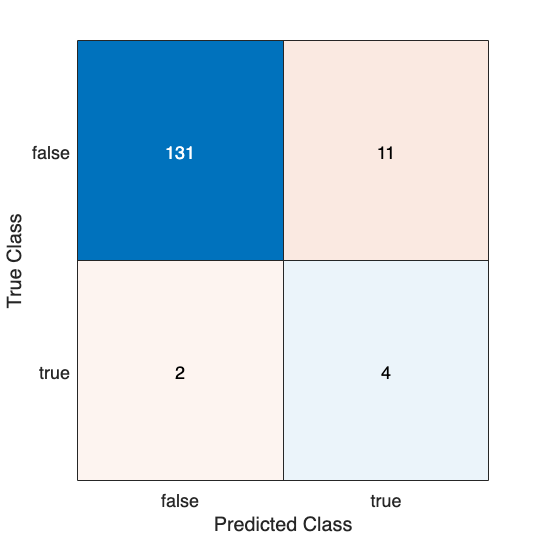

grouphat = false(size(data,1),1);
grouphat(solution.flaggedOutlierIndices) = true;

figure(1);
cm = confusionchart(data.outlier, grouphat);
set(gcf,'Position',[100, 100, 300, 300]);


true_negatives = cm.NormalizedValues(1,1);
false_negatives = cm.NormalizedValues(2,1);

true_positives = cm.NormalizedValues(2,2);
false_positves = cm.NormalizedValues(1,2);

accuracy = (true_positives + true_negatives)/size(data, 1);
precision = true_positives / (true_positives + false_positves);
sensitivity = true_positives / (true_positives + false_negatives);
specificity = true_negatives / (true_negatives + false_positves);

table(accuracy, precision, sensitivity, specificity)

ans = 1×4 table
    accuracy    precision    sensitivity    specificity
    ________    _________    ___________    ___________

    0.91216      0.26667       0.66667        0.92254  


hSubsetRelativeSize = 0.5:0.05:1;
objectiveValues = zeros(size(hSubsetRelativeSize));
for i=1:numel(hSubsetRelativeSize)
    objectiveValues(i) = poc.runAlgorithm(x, hSubsetRelativeSize(i)).obj;
end

Convergence at iteration 2, SDO
Convergence at iteration 1, SpatialRank
Convergence at iteration 1, SpatialMedian
Convergence at iteration 3, SSCM
-> Best estimator is SSCM
Convergence at iteration 2, SDO
Convergence at iteration 1, SpatialRank
Convergence at iteration 1, SpatialMedian
Convergence at iteration 2, SSCM
-> Best estimator is SpatialMedian
Convergence at iteration 6, SDO
Convergence at iteration 2, SpatialRank
Convergence at iteration 2, SpatialMedian
Convergence at iteration 2, SSCM
-> Best estimator is SSCM
Convergence at iteration 5, SDO
Convergence at iteration 2, SpatialRank
Convergence at iteration 1, SpatialMedian
Convergence at iteration 2, SSCM
-> Best estimator is SSCM
Convergence at iteration 3, SDO
Convergence at iteration 2, SpatialRank
Convergence at iteration 1, SpatialMedian
Convergence at iteration 2, SSCM
-> Best estimator is SSCM
Convergence at iteration 2, SDO
Convergence at iteration 1, SpatialRank
Convergence at iteration 1, SpatialMedian
Convergence 

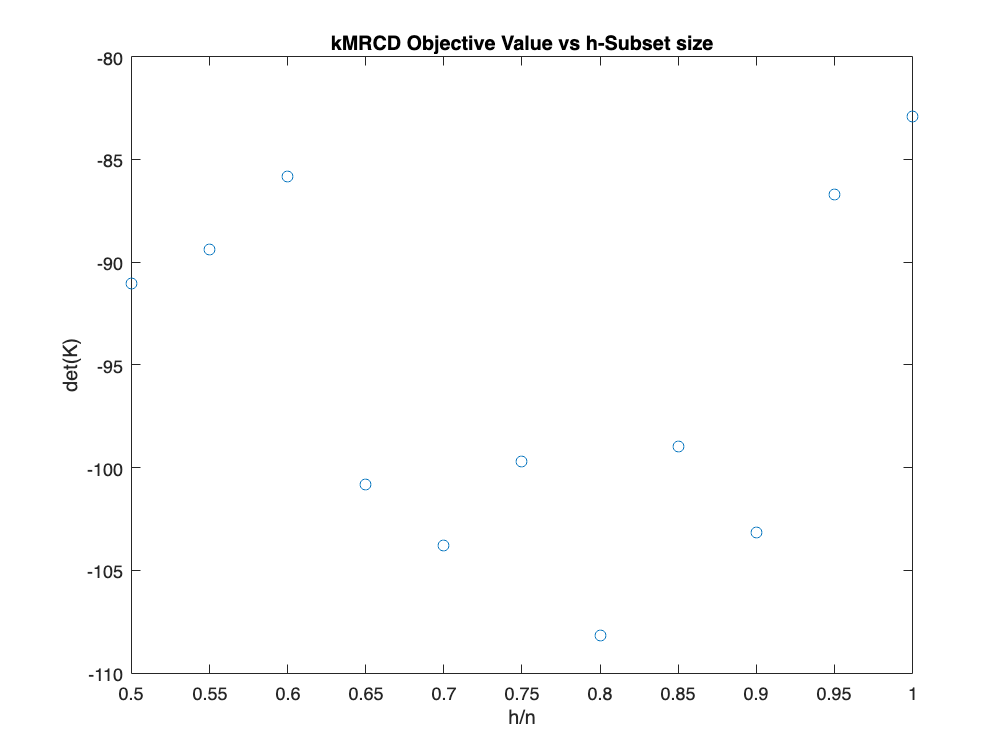

figure(2);
plot(hSubsetRelativeSize, objectiveValues, 'o')
title('kMRCD Objective Value vs h-Subset size')
xlabel('h/n')
ylabel('det(K)')